t = 9;
M = 10;
variance = 0.02;
samples = 1000;
E_oil = 3;
E_air = 1;
frequency = [4 12];
ks = 0;
tmin = 0;
tmax = 10;
thickness_step = 1;
temp = 20;
salinity = 35;
theta = 0;


Scatter plot demo

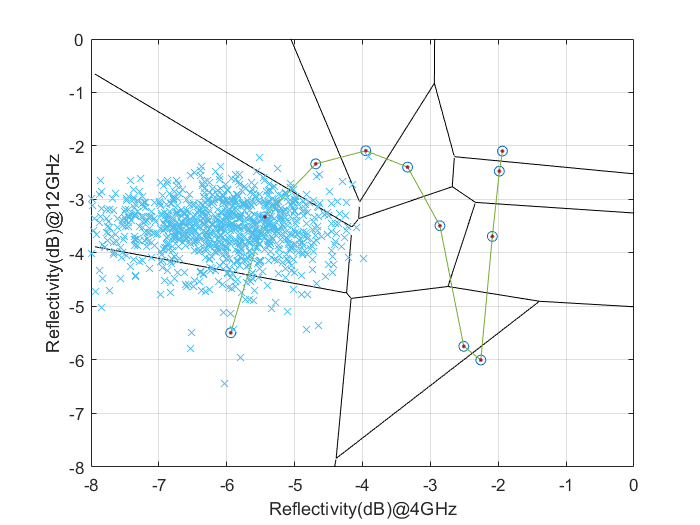

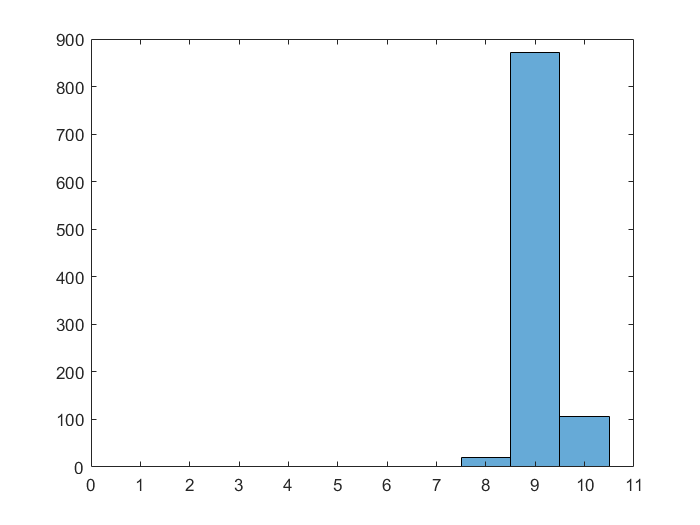



[Estimated_thickness, MaximumError, probability_of_error] = scatterplot(M, frequency, ks, t, variance, samples, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);

Estimate_Thickness demo



thickness = tmin:thickness_step:tmax;
measured_reflectivities = double.empty;

random_thicknesses = (tmax-tmin).*rand(10, 1) + tmin

random_thicknesses =     9.1334
    4.5610
    3.5833
    5.7222
    2.5457
    3.1106
    2.0493
    8.1039
    8.1466
    2.2703



%generate reflectivity values
for i =1:1:length(frequency)
    measured_reflectivities(:, :, i) = reflectivity(frequency(i), random_thicknesses, ks, E_oil, E_air, temp, salinity, theta);
end

Estimated_thicknesses = Estimate_Thickness(measured_reflectivities, M, frequency, ks,  variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax)

Estimated_thicknesses =      8
     5
     3
     7
     4
     4
     2
     8
     8
     2
